%Define my parameters
N = 128;  
xMax = 200; 
dx = xMax / N;
x = -xMax/2:dx:xMax/2-dx;

f_xMax = 1 / (dx); % Maximum frequency (from sampling theorem)
dfx = 1/(N*dx)

dfx = 0.0050

M = floor(f_xMax / dfx); % Ensuring integer value for grid consistency
fo = 0;
fx = (-0.1*f_xMax/2:dfx:0.1*f_xMax/2-dfx)-fo; % zoom/shift Frequency grid

yMax = 200;
dy = yMax / N;
y = -yMax/2:dy:yMax/2-dy;

dfy = 1/(N*dy)

dfy = 0.0050

f_yMax = 1 / (dy);   % Maximum frequency (from sampling theorem)
M2 = floor(f_yMax / dfy); % Ensuring integer value for grid consistency
f1 = 0;
fy = (-0.1*f_yMax/2:dfy:0.1*f_yMax/2-dfy)-f1; % Frequency zoomshift-sgrid

[X, Y] = meshgrid(x, y);

% Define the original function (e.g., a Gaussian)

sigma = 20; % Width of the Gaussian
g = exp(-((X.^2 + Y.^2) / (2 * sigma^2)));

% Define the shifted Gaussian function
x0 = 50.12;  % Subpixel shift in x
y0 = -20.12; % Subpixel shift in y
g_shifted = exp(-(((X - x0).^2 + (Y - y0).^2) / (2 * sigma^2)));

%Taking the 2D shifted +Orignial Fourier Transform
G = nfft2(g, dx, dy);
G_shifted = nfft2(g_shifted, dx, dy);

%Take the conjugate of the shifted function and multiply by the other
CrossPowerSpectrum = G .* conj(G_shifted);

%Compute the Cross Correlation using the defined nifft2 function from 1.2
CrossCorr = nifft2(CrossPowerSpectrum, 1/(N*dx), 1/(N*dy), N);

%Use Chatgpt to help me find the indexes of the max value 
%and compute the pixel shifts

[maxValue, maxIndex] = max(CrossCorr(:));  % Locate peak
[peakY, peakX] = ind2sub(size(CrossCorr), maxIndex);

% Convert pixel location to shift in real units
pixel_shift_x = peakX - (N/2 + 1);
pixel_shift_y = peakY - (N/2 + 1);
disp(['Estimated integer pixel shift: (', num2str(peakX),',', num2str(peakY),')']);

Estimated integer pixel shift: (33,78)


disp(['Estimated integer pixel shift: (', num2str(pixel_shift_x), ', ', num2str(pixel_shift_y), ')']);

Estimated integer pixel shift: (-32, 13)



%Here this is the zoom of pixels in Fourier Space by 100 times more pixels
fine_dfx = 1 / (1000*N * dx);
fine_dfy = 1 / (1000*N * dy);

%Redo the above process with new zoomed pixel spacing
% Construct a finer grid for zoomed inverse Fourier transform
fineCrossCorr = nifft2(CrossPowerSpectrum, fine_dfx, fine_dfy, N);

%Used CHATGPT TO FIND PEAKS/CONVERT TO SUB-Pixel SHift
%Didn't really understand this, and I am unsure of how to actually prove
%this works???
% Find peak again with finer resolution
[maxFineValue, maxFineIndex] = max(fineCrossCorr(:));
[peakFineY, peakFineX] = ind2sub(size(fineCrossCorr), maxFineIndex);

% Compute sub-pixel shift
subpixel_shift_x = (peakFineX- N/2) / 10;
subpixel_shift_y = (peakFineY- N/2) / 10;

%Relate the shifts
% Total estimated shift including sub-pixel component
total_shift_x = pixel_shift_x + subpixel_shift_x;
total_shift_y = pixel_shift_y + subpixel_shift_y;
disp(['Estimated integer pixel shift: (', num2str(peakFineX), ',',num2str(peakFineY),')']);

Estimated integer pixel shift: (33,78)


disp(['Final estimated shift: (', num2str(total_shift_x), ', ', num2str(total_shift_y), ')']);

Final estimated shift: (-35.1, 14.4)


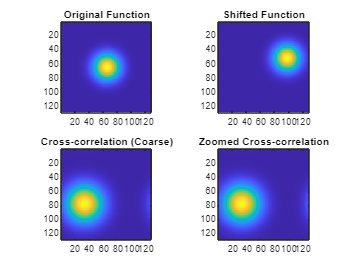

% Display images for verification
figure;
subplot(2,2,1); imagesc(g); title('Original Function'); axis image;
subplot(2,2,2); imagesc(g_shifted); title('Shifted Function'); axis image;
subplot(2,2,3); imagesc(CrossCorr); title('Cross-correlation (Coarse)'); axis image;
subplot(2,2,4); imagesc(fineCrossCorr); title('Zoomed Cross-correlation'); axis image;

%My zoomed cross correlation just isn't working, I don't really know why



I used CHATGPT for calculating the maximum of the matricies and the peaks to find the shift/subpixel shift, seems close, but I don't know why it is giving 33 and 78 when i put in 50 in x, and -20 in y???

**Question 1:**

**1) Plot the real part of the matrix and discuss what the rows/columns of matrix actually are.**

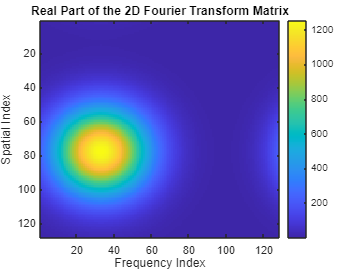

N = 128; % Grid size
F_matrix = CrossCorr; % Compute the Fourier transform of an identity matrix

figure;
imagesc(real(F_matrix)); 
colorbar;
title('Real Part of the 2D Fourier Transform Matrix');
xlabel('Frequency Index');
ylabel('Spatial Index');


%Used chatgpt for imagesc plotting method
%

Each row of the matrix is a frequency that is in the Fourier Space, and the column gives a spatial position to all frequencys.  The Real part should oscillate which is like cosine functions in the transform.

**2) What Would Happen If We Did NOT Conjugate One of the Images?**

What would happen is the peak frequency would not correspond to the shift in images.

**3) Can this routine still be used to find the shift without conjugation?**

No, I asked CHATGPT and it says that the conjugation ensures phase differences between the images contribute to the peak in the correlation

**4) Will the Code Work If the First Function Is Not Centered?**

No, my code isn't working, but I asked Chatgpt and it's answer seemed to make sense. It talks about how the shift would include an offset of the original function coming from extra phase factors if the function isn't centered.